%% the code and raw LDs spectra for HybridPCA denoising.

% load raw Raman spectra.
load('spec_cosfa.mat')
load('spec_cosoa.mat')
load('spec_cosst.mat')
load('spec_plcfa.mat')
load('spec_plcoa.mat')
spec = [ldsSpec_cosfa;ldsSpec_cosoa;spec_plcfa;spec_plcoa;spec_cosst];

x = 255:955;
pxpx = [423 438 502 663 742.5 754];
wnpx = [1001.4 1031.8 1155.3 1450.5 1583.1 1602.3];
wn = polyval(polyfit(pxpx,wnpx,2),1:1024); 

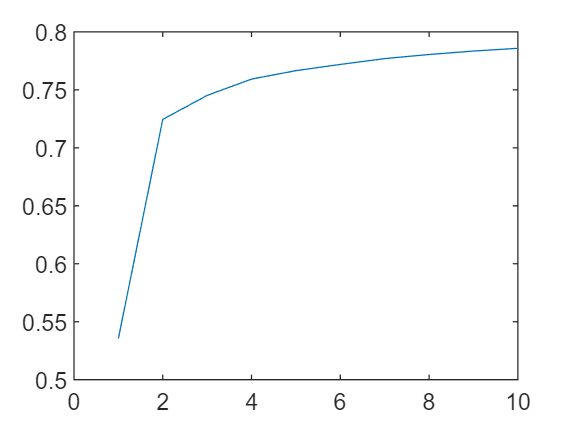

% PCA analysis.
[c,s,score] = pca(spec);
xle = 10;
for ii = 1:xle
    sor(ii) = sum(score(1:ii))/sum(score);
end
plot(1:xle,sor)

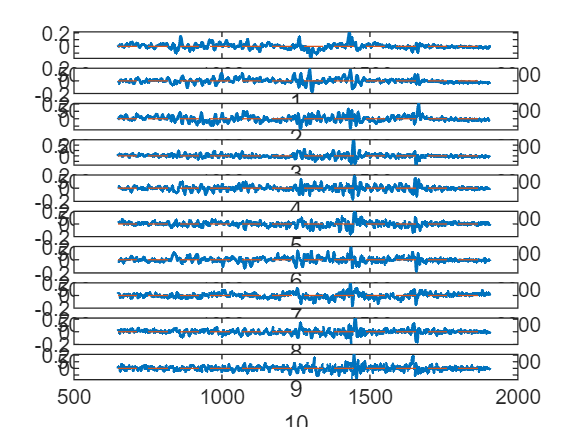

figure
for ii = 1:10
    subplot(10,1,ii)
    plot(wn(x),c(:,ii + 10),'LineWidth',1.2),xlabel(num2str(ii));
    hold on
    plot(wn(x),zeros(length(x),1),'--','LineWidth',0.5)
end

% calculate the contribution of each PCA component.
data = spec;
num = 700;
[c,s,v] = pca(data);
v_l = v./sum(v);
 
 for ij = 1:size(data,1)
   mean_spec(ij,:) = data(ij,:) - mean(data);
   new_s = (mean_spec(ij,:)*c)';
   for jk = 1:num
   Spec = c(:,1:jk)*new_s(1:jk);
   SNR(ij,jk) =log10(data(ij,:).^2/((data(ij,:)-(mean(data)+Spec')).^2));
   end
 end

 for ij = 1:size(SNR,2)-1
     delta_SNR(:,ij) = SNR(:,ij+1)-SNR(:,ij);
 end
 Delta_SNR = mean([SNR(:,1),delta_SNR]);

figure
clf
plot(1:num,Delta_SNR)
xlabel('PCs');
ylabel('SNR contribution');
xlim([1,num])
ylim([-0.1,0.1])
set(gca,'FontSize',24)

% choose a proper throldhold to reconstruct the spectra.
thr2 = 0.006;
name_list = {find(Delta_SNR>thr2)};
for ij = 1:size(data,1)
    mean_spec(ij,:) = data(ij,:) - mean(data);
    new_s(:,ij) = (mean_spec(ij,:)*c)';
    Spec = c(:,[cell2mat(name_list)])*new_s([cell2mat(name_list)],ij);
    Reconstructed(ij,:) = mean(data)+Spec';
end 
Index_selected = cell2mat(name_list);
filename = strcat('spect50x.mat');
save(filename,'Reconstructed');